**The simulations of the modified model where X is not necessary for transcription. **

**For Figure S2.**

% Basic paramters
load ../Parameter_determination/Basic_parameters.mat

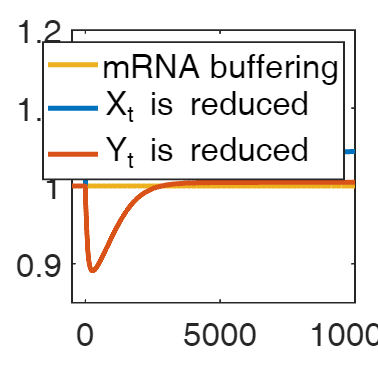


% Modify the basic paramters
k0=para_opt(1)/8;
k1=para_opt(1)/4;
am=para_opt(5);
ax=para_opt(6);
ay=para_opt(7);
bx=para_opt(9);
bm=para_opt(8);
Kx=para_opt(2);
Km=para_opt(4);
Vn=2.8;
Vc=37.2;
Kv=5.8262;
Ky=para_opt(3);
Xt=para_opt(10);
Yt=para_opt(11);


% Initialization
mn0=Vn*ay/am;
mc0=Vc*bx/bm;
Xn0=10000;
Xc0=50000;
Xp0=Xt-Xn0-Xc0;
Yn0=1000;
Yp0=Yt-Yn0;

dt=1;
T=100000;
nperm=T/dt;

mn_tot=zeros(1,nperm);
mc_tot=zeros(1,nperm);
Xn_tot=zeros(1,nperm);
Xc_tot=zeros(1,nperm);
Xp_tot=zeros(1,nperm);
Yn_tot=zeros(1,nperm);
Yp_tot=zeros(1,nperm);
Vn_tot=zeros(1,nperm);
Vc_tot=zeros(1,nperm);

dmndt_tot=zeros(1,nperm);
dmcdt_tot=zeros(1,nperm);
dXndt_tot=zeros(1,nperm);
dXcdt_tot=zeros(1,nperm);
dXpdt_tot=zeros(1,nperm);
dYndt_tot=zeros(1,nperm);
dYpdt_tot=zeros(1,nperm);
vpro0_tot=zeros(1,nperm);
vprop_tot=zeros(1,nperm);
vdeg_tot=zeros(1,nperm);


%%% Depletion of X
for i=1:(T/dt)

    if i==1
        mn=mn0;
        mc=mc0;
        Xn=Xn0;
        Xc=Xc0;
        Xp=Xp0;
        Yp=Yp0;
        Yn=Yn0;
    elseif i==0.2*T/dt
        mn=mn_next;
        mc=mc_next;
        Xn=Xn_next*0.05; %depletion
        Xc=Xc_next*0.05; %depletion
        Xp=Xp_next*0.05; %depletion
        Yp=Yp_next;
        Yn=Yn_next;

    else
        mn=mn_next;
        mc=mc_next;
        Xn=Xn_next;
        Xc=Xc_next;
        Xp=Xp_next;
        Yp=Yp_next;
        Yn=Yn_next;
    end

    kn_oth=(Vn/(Vn+Kv))*Vn*Km/(Vn*Km+mn);
    kn0=k0*(Kx*Vn/(Xp+Kx*Vn))*Ky*Vn/(Yp+Ky*Vn)*kn_oth;
    knp=k1*(Xp/(Xp+Kx*Vn))*Yp/(Yp+Ky*Vn)*kn_oth;


    dmndt=kn0+knp-am*(Yn/Vn)*mn;
    dXndt=knp-ax*Xn;
    dXcdt=ax*Xn-bx*Xc;
    dmcdt=am*(Yn/Vn)*mn-bm*(Xc/Vc)*mc;
    dXpdt=bx*Xc-knp;
    dYpdt=ay*Yn-knp;
    dYndt=knp-ay*Yn;

    mn_next=mn+dmndt*dt;
    mc_next=mc+dmcdt*dt;
    Xn_next=Xn+dXndt*dt;
    Xc_next=Xc+dXcdt*dt;
    Xp_next=Xp+dXpdt*dt;
    Yp_next=Yp+dYpdt*dt;
    Yn_next=Yn+dYndt*dt;



    mn_tot(i)=mn;
    mc_tot(i)=mc;
    Xn_tot(i)=Xn;
    Xc_tot(i)=Xc;
    Xp_tot(i)=Xp;
    Yn_tot(i)=Yn;
    Yp_tot(i)=Yp;
    Vn_tot(i)=Vn;
    Vc_tot(i)=Vc;

    dmndt_tot(i)=dmndt;
    dmcdt_tot(i)=dmcdt;
    dXndt_tot(i)=dXndt;
    dXcdt_tot(i)=dXcdt;
    dXpdt_tot(i)=dXpdt;
    dYndt_tot(i)=dYndt;
    dYpdt_tot(i)=dYpdt;
    vpro0_tot(i)=kn0;
    vprop_tot(i)=knp;
    vdeg_tot(i)=bm*(Xc/Vc)*mc;
end

cm_x=(mn_tot+mc_tot)./(Vn_tot+Vc_tot);



%%% Depletion of Y
for i=1:(T/dt)

    if i==1
        mn=mn0;
        mc=mc0;
        Xn=Xn0;
        Xc=Xc0;
        Xp=Xp0;
        Yp=Yp0;
        Yn=Yn0;
    elseif i==0.2*T/dt
        mn=mn_next;
        mc=mc_next;
        Xn=Xn_next;
        Xc=Xc_next;
        Xp=Xp_next;
        Yp=Yp_next*0.01; %depletion
        Yn=Yn_next*0.01; %depletion

    else
        mn=mn_next;
        mc=mc_next;
        Xn=Xn_next;
        Xc=Xc_next;
        Xp=Xp_next;
        Yp=Yp_next;
        Yn=Yn_next;
    end

    kn_oth=(Vn/(Vn+Kv))*Vn*Km/(Vn*Km+mn);
    kn0=k0*(Kx*Vn/(Xp+Kx*Vn))*Ky*Vn/(Yp+Ky*Vn)*kn_oth;
    knp=k1*(Xp/(Xp+Kx*Vn))*Yp/(Yp+Ky*Vn)*kn_oth;


    dmndt=kn0+knp-am*(Yn/Vn)*mn;
    dXndt=knp-ax*Xn;
    dXcdt=ax*Xn-bx*Xc;
    dmcdt=am*(Yn/Vn)*mn-bm*(Xc/Vc)*mc;
    dXpdt=bx*Xc-knp;
    dYpdt=ay*Yn-knp;
    dYndt=knp-ay*Yn;

    mn_next=mn+dmndt*dt;
    mc_next=mc+dmcdt*dt;
    Xn_next=Xn+dXndt*dt;
    Xc_next=Xc+dXcdt*dt;
    Xp_next=Xp+dXpdt*dt;
    Yp_next=Yp+dYpdt*dt;
    Yn_next=Yn+dYndt*dt;



    mn_tot(i)=mn;
    mc_tot(i)=mc;
    Xn_tot(i)=Xn;
    Xc_tot(i)=Xc;
    Xp_tot(i)=Xp;
    Yn_tot(i)=Yn;
    Yp_tot(i)=Yp;
    Vn_tot(i)=Vn;
    Vc_tot(i)=Vc;

    dmndt_tot(i)=dmndt;
    dmcdt_tot(i)=dmcdt;
    dXndt_tot(i)=dXndt;
    dXcdt_tot(i)=dXcdt;
    dXpdt_tot(i)=dXpdt;
    dYndt_tot(i)=dYndt;
    dYpdt_tot(i)=dYpdt;
    vpro0_tot(i)=kn0;
    vprop_tot(i)=knp;
    vdeg_tot(i)=bm*(Xc/Vc)*mc;
end

cm_y=(mn_tot+mc_tot)./(Vn_tot+Vc_tot);


% Plot
colors=["#0072BD"
    "#D95319"
    "#EDB120"
    "#7E2F8E"
    "#77AC30"
    "#4DBEEE"
    "#A2142F"
    '#FF0000'
    '#00FF00'
    '#0000FF'
    '#00FFFF'
    '#FF00FF'
    '#FFFF00'
    '#000000'
    '#FFFFFF'];

fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);


scale_time=(1:nperm)-2e4;
p1=plot(scale_time,ones(1,nperm), ...
    "LineWidth",3, ...
    "Color",colors(3),...
    "DisplayName","mRNA buffering");
hold on
p2=plot(scale_time,cm_x/cm_x(1.9e4), ...
    "LineWidth",3, ...
    "Color",colors(1),...
    "DisplayName","X_t is reduced");
hold on
p3=plot(scale_time,cm_y/cm_y(1.9e4), ...
    "LineWidth",3, ...
    "Color",colors(2),...
    "DisplayName","Y_t is reduced");
hold off
xlim([1.95e4,3e4]-2e4)
ylim([0.85,1.2])
set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
legend([p1 p2 p3],"Interpreter","tex","FontSize",20)